M = csvread(deviancy)

M =             0          841
          0.2          841
          0.4          841
          0.6            0
          0.8           58
            1           29
          1.2           29
          1.4           29
          1.6           29
          1.8           58



x = M(:,1)

x =             0
          0.2
          0.4
          0.6
          0.8
            1
          1.2
          1.4
          1.6
          1.8


y = M(:,2)

y =    841
   841
   841
     0
    58
    29
    29
    29
    29
    58



segmentOne = y(1:60,:)

segmentOne =    841
   841
   841
     0
    58
    29
    29
    29
    29
    58


segmentTwo = y(125:185,:)

segmentTwo =     58
     5
    42
    84
    50
   182
   408
   475
   319
   145


segmentThree = y(245:285,:)

segmentThree =    315
   348
   406
   406
   348
   174
     0
   149
   236
   256


segmentFour = y(365:430,:)

segmentFour =    365
   391
   416
   416
   399
   399
   382
   382
   348
   348



overall = max(y)

overall =    841


sOne = max(segmentOne)

sOne =    841


sTwo = max(segmentTwo)

sTwo =    667


sThr = max(segmentThree)

sThr =    783


sFo = max(segmentFour)

sFo =    580


Maximum = [overall; sOne; sTwo; sThr; sFo]

Maximum =    841
   841
   667
   783
   580


Maximum = round(Maximum,3, 'significant')

Maximum =    841
   841
   667
   783
   580



overMean = rms(y)

overMean =        360.21


smOne = rms(segmentOne)

smOne =        211.87


smTwo = rms(segmentTwo)

smTwo =        349.45


smThr = rms(segmentThree)

smThr =        430.64


smFo = rms(segmentFour)

smFo =        332.14


Average = [overMean; smOne; smTwo; smThr; smFo]

Average =        360.21
       211.87
       349.45
       430.64
       332.14


Average = round(Average,3, 'significant')

Average =    360
   212
   349
   431
   332



overSTD = std(segmentOne)

overSTD =        188.53


ssmOne = std(segmentOne)

ssmOne =        188.53


ssmTwo = std(segmentTwo)

ssmTwo =        205.15


ssThr = std(segmentThree)

ssThr =        237.84


ssmFo = std(segmentFour)

ssmFo =        166.12


StandardDeviation = [overSTD; ssmOne; ssmTwo; ssThr; ssmFo]

StandardDeviation =        188.53
       188.53
       205.15
       237.84
       166.12


StandardDeviation = round(StandardDeviation,3, 'significant')

StandardDeviation =    189
   189
   205
   238
   166



Segments = {'Overall';'Segment 1';'Segment 2';'Segment 3';'Segment 4'}

Segments = 5×1 cell array
    {'Overall'  }
    {'Segment 1'}
    {'Segment 2'}
    {'Segment 3'}
    {'Segment 4'}


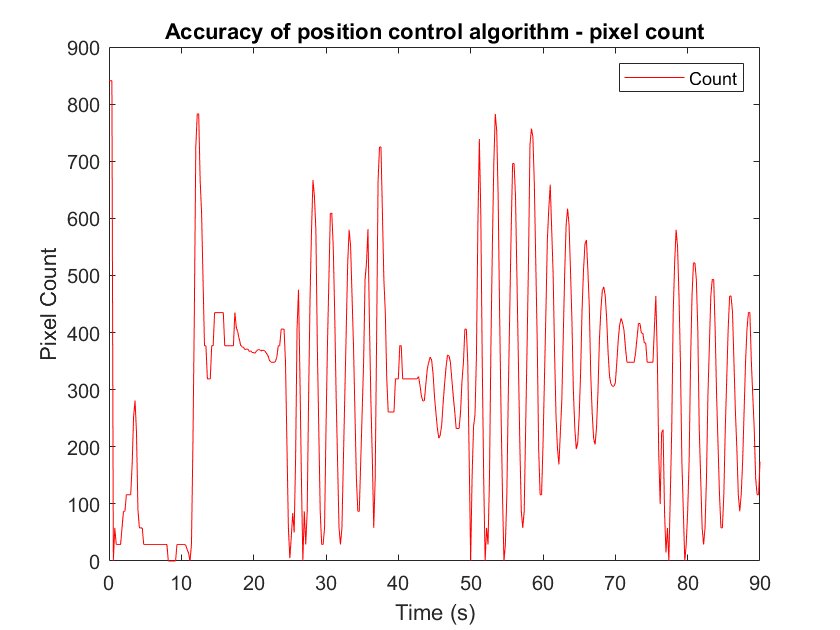


plot(x,y,'r');
xlabel('Time (s)');
ylabel('Pixel Count');
title('Accuracy of position control algorithm - pixel count')
legend({'Count'},'Location','northeast')


SEM = StandardDeviation/sqrt(length(segmentOne))

SEM =          24.4
         24.4
       26.465
       30.726
       21.431


SEM = round(SEM,3, 'significant')

SEM =          24.4
         24.4
         26.5
         30.7
         21.4



T = table(Segments,Maximum, Average,StandardDeviation, SEM)

T = 5×5 table
      Segments       Maximum    Average    StandardDeviation    SEM 
    _____________    _______    _______    _________________    ____

    {'Overall'  }      841        360             189           24.4
    {'Segment 1'}      841        212             189           24.4
    {'Segment 2'}      667        349             205           26.5
    {'Segment 3'}      783        431             238           30.7
    {'Segment 4'}      580        332             166           21.4


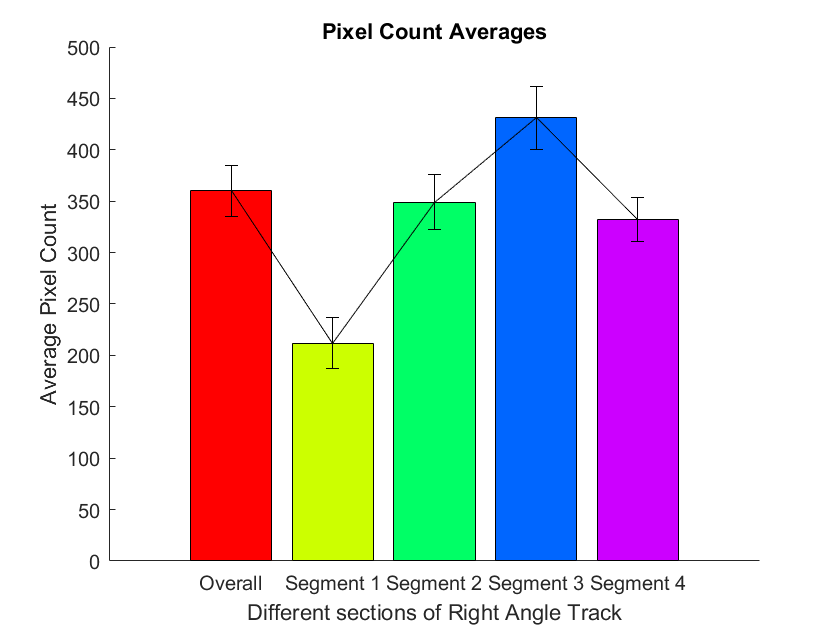


fHand = figure;
aHand = axes('parent', fHand);
hold(aHand, 'on')
colors = hsv(numel(Average));
for i = 1:numel(Average)
    b = bar(i, Average(i), 'parent', aHand, 'facecolor', colors(i,:));
end
set(gca, 'XTick', 1:numel(Average), 'XTickLabel', {'Overall';'Segment 1';'Segment 2';'Segment 3';'Segment 4'})
errorbar(Average, SEM,'k');
title('Pixel Count Averages')
xlabel('Different sections of Right Angle Track')
ylabel('Average Pixel Count')